# Lab 4

Ross Smyth

clear, clc, close all
addpath ADSP_ToolBox\

## Project 1: Z-Transform

###     1. 

####         a.

x = [1, 3, 0, 0, 0, 0];

[xn, xd] = ztr(x);

ix = izt('tf', xn, xd)

ix = '(1*(3 .^n)).*ustep(n)'


$$x\left\lbrack n\right\rbrack ={\left(3\right)}^n u\left\lbrack n\right\rbrack$$


`ix`$=1*3^n *u\left\lbrack n\right\rbrack$

These two expressions are equivalent, therefore the `ztr` function is valid.

####         b.

x1 = [2, 5, 0, 0, 0, 0];
x2 = x;

% Superposition means we can add these together post z-transform
[x1n, x1d] = ztr(x1);
x2n = xn;
x2d = xd;


$$X\left\lbrack z\right\rbrack =\frac{2z^1 +0}{z^1 -5}+\frac{z^1 +0}{z^1 -3}=\frac{2z\left(z-3\right)}{\left(z-5\right)\left(z-3\right)}+\frac{z\left(z-5\right)}{\left(z-5\right)\left(z-3\right)}=\frac{2z\left(z-3\right)+z\left(z-5\right)}{\left(z-5\right)\left(z-3\right)}=\frac{3z^2 -11z}{\left(z-5\right)\left(z-3\right)}$$


xtotn   = [3, -11, 0];
xtotd_r = [5, 3];

izt('tf', xtotn, xtotd_r, 1)

ans = '(2*(5 .^n)+1*(3 .^n)).*ustep(n)'


$$x\left\lbrack n\right\rbrack =2{\left(5\right)}^n u\left\lbrack n\right\rbrack +{\left(3\right)}^n u\left\lbrack n\right\rbrack$$


The output of `izt` is:


$$x\left\lbrack n\right\rbrack =\left(2\left(5^n \right)+1\left(3^n \right)\right)u\left\lbrack n\right\rbrack$$


These expressions are equivalent, therefore `izt` is validated again.

###     2.

####         a.


$$y\left\lbrack n\right\rbrack -0\ldotp 7y\left\lbrack n-1\right\rbrack =2x\left\lbrack n\right\rbrack$$



$$\frac{Y\left(z\right)}{X\left(z\right)}=\frac{2z}{z-0\ldotp 7}$$


####         b.


$$y\left\lbrack n\right\rbrack +0\ldotp 7y\left\lbrack n-1\right\rbrack =2x\left\lbrack n\right\rbrack$$



$$\frac{Y\left(z\right)}{X\left(z\right)}=\frac{2z}{z+0\ldotp 7}$$


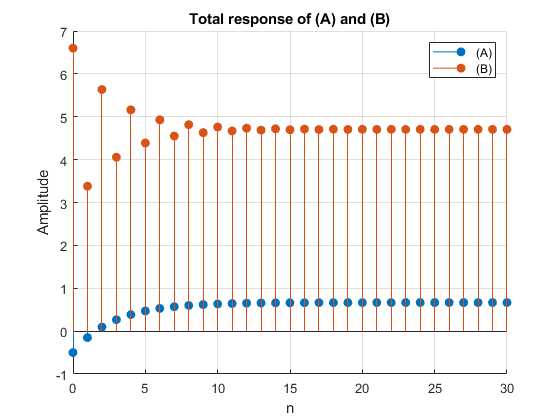

n = 0:30;

% a
[xna, xda] = ztr([0.1, 1, 0, 0, 0, 0]);
[yta_e, ~, ~] = sysresp2('z', [2, 0], [1, -0.7], xna, xda, -1);
yta = eval(yta_e);

% b
[xnb, xdb] = ztr([4, 1, 0, 2*pi, 0, 0]);
[ytb_e, ~, ~] = sysresp2('z', [2, 0], [1, 0.7], xnb, xdb, 2);
ytb = eval(ytb_e);

% Plotting
figure()
hold on
stem(n, yta, 'filled')
stem(n, ytb, 'filled')

title('Total response of (A) and (B)')
xlabel('n')
ylabel('Amplitude')
legend({'(A)', '(B)'})
grid

hold off


final_a = yta(end)

final_a = 0.6666

final_b = ytb(end)

final_b = 4.7059

The total response of both difference equation are the following:


$$\begin{array}{l}
y_{t,a} \left\lbrack n\right\rbrack =0\ldotp 66667-1\ldotp 1667{\left(-0\ldotp 7\right)}^n u\left\lbrack n\right\rbrack \\
y_{t,a} \left\lbrack n\right\rbrack =4\ldotp 7059+1\ldotp 8941{\left(-0\ldotp 7\right)}^n u\left\lbrack n\right\rbrack 
\end{array}$$


The exponential terms as the limit of n approaches infinity go to zero, so the constant terms are the steadt-state response value.

For a that value is 0.66667

For b that value is $4\ldotp 7059$

These are both very close to the final value that was evaluated and plotted above, meaning the plot at `n=30` is near steady-state.

## Project 2: Noisy ECG

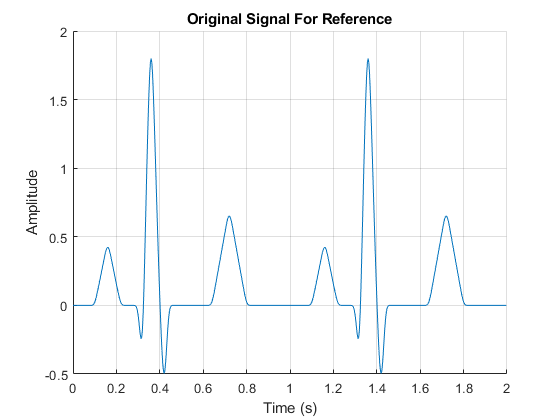

clear, clc, close all
load ecg
load ecgo

figure()
hold on
plot(0:1/300:(2-1/300), ecgo)

title('Original Signal For Reference')
xlabel('Time (s)')
ylabel('Amplitude')
grid
hold off


$$H_1 \left\lbrack z\right\rbrack =\left(1-e^{\mathrm{j0}\ldotp 4\pi } z^{-1} \right)\left(1-e^{-\mathrm{j0}\ldotp 4\pi } z^{-1} \right)=\frac{z^2 -0\ldotp 618034z+1}{z^2 }$$


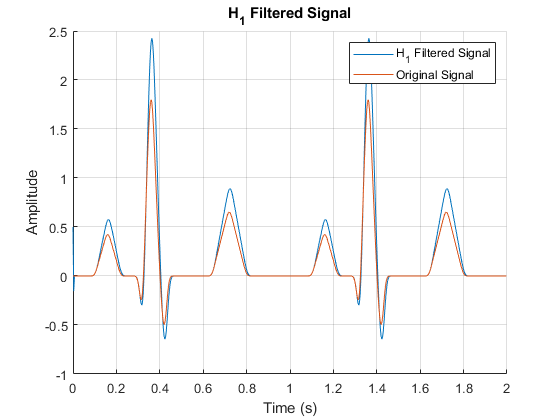

h1 = filter([1, -0.618034, 1], [1, 0, 0], ecg);

figure()
hold on
plot(0:1/300:(2-1/300), h1)
plot(0:1/300:(2-1/300), ecgo)

title('H_1 Filtered Signal')
xlabel('Time (s)')
ylabel('Amplitude')
legend({'H_1 Filtered Signal', 'Original Signal'})
grid
hold off

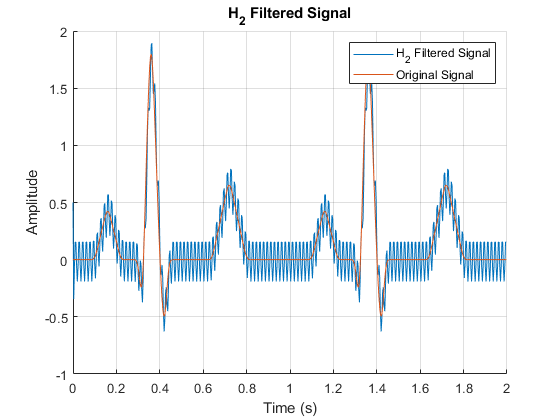

h2 = filter([1, -1, 1], 1, ecg);

figure()
hold on
plot(0:1/300:(2-1/300), h2)
plot(0:1/300:(2-1/300), ecgo)

title('H_2 Filtered Signal')
xlabel('Time (s)')
ylabel('Amplitude')
legend({'H_2 Filtered Signal', 'Original Signal'})
grid
hold off

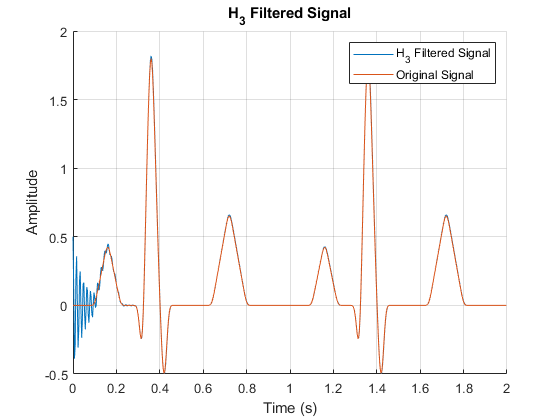

h3 = filter([1, -0.618, 1], [1, -0.518, 0.8836], ecg);

figure()
hold on
plot(0:1/300:(2-1/300), h3)
plot(0:1/300:(2-1/300), ecgo)

title('H_3 Filtered Signal')
xlabel('Time (s)')
ylabel('Amplitude')
legend({'H_3 Filtered Signal', 'Original Signal'})
grid
hold off

####         b.

Of the filters, $H_1$ and $H_3$ and able to attenuate the 60 Hz noise from the ECG signal. $H_2$ still leaves a lot of the frequency content in the signal as seen in the plot above.

####         c. 

The filter that does the best job is $H_3$ the 60 Hz signal is attenuated almost completely. It's primary problem is that there are some start-up transients with the filter response, so the first 0.2 seconds or so are not filtered well. $H_1$ does not have this problem, but it distorts the gain of the signal, therefore skewing the results that could be important.

## Project 3: Echo Cancellation

###     a.

#### Sampled:


$$t\Rightarrow \frac{n}{8192}$$



$$c\left\lbrack n\right\rbrack =s\left(\frac{n}{8192}\right)+0\ldotp 9s\left(\frac{n}{8192}-\frac{93\ldotp 75}{1000}\right)+0\ldotp 8s\left(\frac{n}{8192}-\frac{187\ldotp 5}{1000}\right)$$


#### Difference equation:


$$c\left\lbrack n\right\rbrack =s\left(n\right)+0\ldotp 9s\left(n-768\right)+0\ldotp 8s\left(n-1536\right)$$


#### Impulse response:


$$\left\lbrack \begin{array}{cccccc}
n & 1 & \ldotp \ldotp \ldotp  & 768 & \ldotp \ldotp \ldotp  & 1536\\
\mathrm{response} & 1 & 0 & 0\ldotp 9 & 0 & 0\ldotp 8
\end{array}\right\rbrack$$


Where "$\ldotp \ldotp \ldotp$" represents zeros in the response

#### Transfer function:


$$H\left\lbrack z\right\rbrack =\frac{C\left\lbrack z\right\rbrack }{S\left\lbrack z\right\rbrack }=\frac{z^{1536} +0\ldotp 9z^{768} +0\ldotp 8}{z^{1536} }$$


This is a FIR filter. This is because all the poles are at the origin and it is casual.

###     b.


$$H_I \left\lbrack z\right\rbrack =\frac{z^{1536} }{z^{1536} +0\ldotp 9z^{768} +0\ldotp 8}$$


This inverse filter is an IIR filter because it is anti-casual (looks at future values), and the poles are not at z=$\infty$

###     c.

load echosig
%sound(echosig)

Listening to the sound, it sounds like 

"The FCC is fine." 

but it's very muddled, and I doubt that's what is being said.

###     d.

hId = zeros(1, 1536);
hId(1) = 1;
hId(1536-768+1) = 0.9;
hId(end) = 0.8;

filtered_echo = filter(1, hId, echosig);
sound(filtered_echo)

Listening to the filtered signal, I think what is being said is "DFT is fine."

I agree with this statement as long as the sample rate of the signal being analyzed is higher than the Nyquist frequency of the feature of interest.

Not all of the reverb is removed with this fitler, though it is reduced significantly. There is also another artifact introduced into the signal. There is a sound that gets louder as sound plays at a highish frequency.